clear all; clc; close all;

j_rviz = [0.573,0.144,0.762,0.573,-1.153]';
% DH parameters:
dh = table;
dh.theta =     [pi/2, -1.4350, -0.028647, pi/2, 0, pi/2]';
dh.d =         [0.0563, 0, 0, 0, 0, 0.114]';
dh.a =         [0, 0.1093, 0.100512, 0, 0, -0.007]';
dh.alpha =     [-pi/2, 0, 0, pi/2, 0, 0]';

% Desired pose:
H = generate_desired_pose(-0.1207,0.1951,0.219578,0,-1.153)

H =    -0.3451   -0.7773   -0.5261   -0.1207
   -0.2135   -0.4809    0.8504    0.1951
   -0.9140    0.4057    0.0000    0.2196
         0         0         0    1.0000


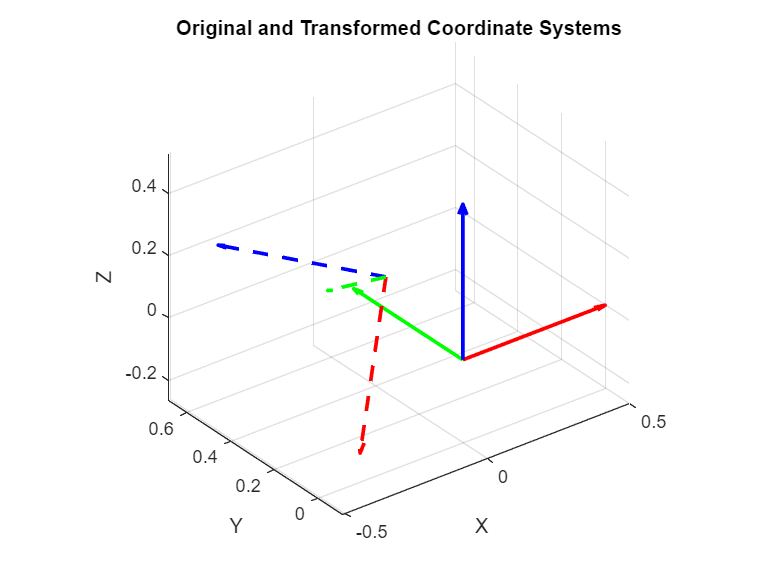

figure
hold on
plotCoordinateSystems(H,1)
hold off

% Inverse kinematics:
j = ik_geometric(H,dh)

j =     2.1494
   -1.3007
    0.7623
    2.1092
   -1.1523


j_ref = j_rviz + dh.theta(1:5)

j_ref =     2.1438
   -1.2910
    0.7334
    2.1438
   -1.1530


mean_abs_error = mean(abs(abs(j)-abs(j_ref)))

mean_abs_error = 0.0159

dh.theta(1:5) = j;

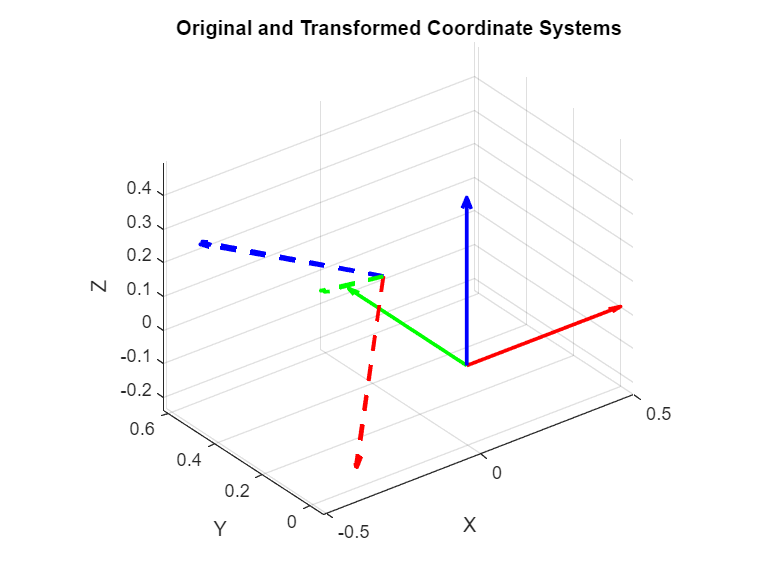

figure
hold on
T = eye(4,4);
for i=1:numel(dh.theta)
    T = T * getDHmatrix(dh(i,:));
    % plotCoordinateSystems(T,0)
end
plotCoordinateSystems(T,0)
plotCoordinateSystems(H,1)
hold off